# Actividad 5.2: Control de Posición

- **Daniel Castillo López A01737357**

- **Emmanuel Lechuga Arreola A01736241**

- **Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear
close all
clc

## Gato

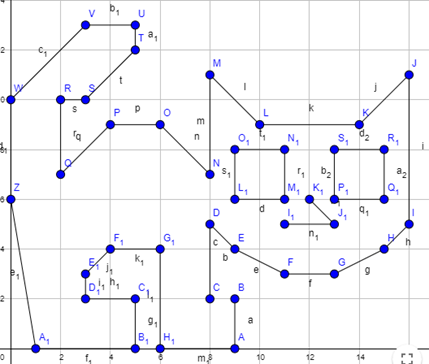

### Control en lazo abierto

### Control en lazo cerrado

## Murciélago

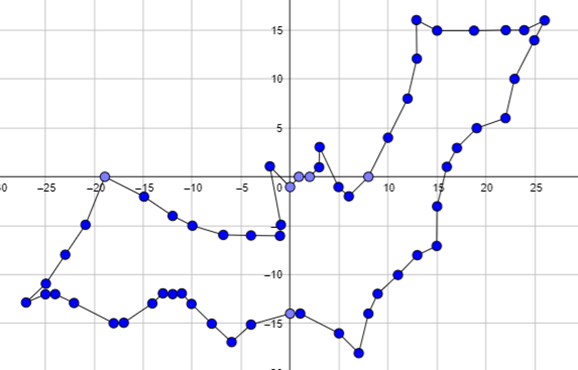

### Control en lazo abierto

### Control en lazo cerrado

## Mariposa

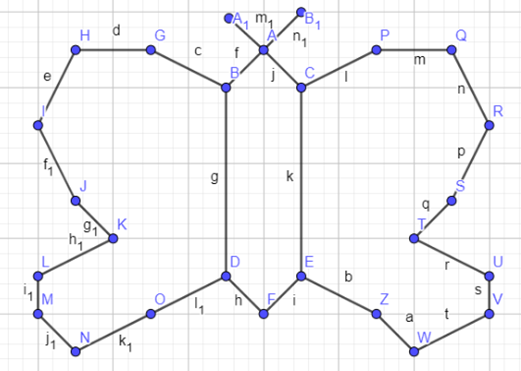

### Control en lazo abierto

#### Velocidades de referencia

Se comienza definiendo los vectores de referencia de velocidad.  Esta secuencia está pensada para simular un movimiento cuadrado en el plano.

u = [zeros(1, 10), 1.25*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10)];
w = [deg2rad(-42.4)*ones(1, 10), zeros(1, 10), deg2rad(-2.6)*ones(1, 10), zeros(1, 10), deg2rad(71.57)*ones(1, 10), zeros(1, 10), deg2rad(-26.57)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-53.43)*ones(1, 10), zeros(1, 10), deg2rad(-18.43)*ones(1, 10), zeros(1, 10), deg2rad(108.43)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-71.57)*ones(1, 10), zeros(1, 10), deg2rad(18.43)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(180)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10), deg2rad(71.57)*ones(1, 10), zeros(1, 10), 0*ones(1, 10), zeros(1, 10), deg2rad(-71.57)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(108.43)*ones(1, 10), zeros(1, 10), deg2rad(-18.43)*ones(1, 10), zeros(1, 10), deg2rad(-53.13)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-26.57)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(180)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), 0*ones(1, 10), zeros(1, 10)];

#### Tiempo

A continuación, se establecen los parámetros temporales. El número de muestras `N` se obtiene a partir de la longitud del vector `u`, mientras que el tiempo de muestreo se define como `ts = 0.1` segundos. El vector de tiempo `t` se genera con una distribución lineal.

N = length(u);
tf = N*2;
ts = 0.1;
t = linspace(0, ts, N);

#### Condiciones iniciales

Las condiciones iniciales del robot se fijan en el origen del plano, con orientación cero. Los vectores `x1`, `y1` y `phi` representan respectivamente la posición en el eje X, el eje Y y la orientación del robot a lo largo de toda la simulación.

x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);

Se establece la coordenada inicial, asignando los valores explícitamente en la primera posición de cada vector. 

x1(1) = 7.08;
y1(1) = 9.84;
phi(1) = 0;

#### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1);

#### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. En cada iteración, se actualiza la orientación `phi` del robot utilizando integración numérica con el método de Euler. Luego, se calculan las componentes de la velocidad en los ejes X y Y considerando la orientación recién calculada. Con esas velocidades, también mediante Euler, se actualiza la posición del robot. Finalmente, se actualiza la trayectoria del punto de control con las nuevas coordenadas del centro del robot.

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

#### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

**a) Configuracion de escena**

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([0 15 0 15 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar Trayectorias**

H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);

**d) Bucle de simulacion de movimiento del robot**

Se dibuja el robot en su posición inicial mediante una función externa (`MobilePlot_4`) que toma como parámetros la posición, orientación y una escala de visualización. Luego, se dibuja la primera parte de la trayectoria del punto de control en color rojo. El bucle de simulación gráfica recorre los pasos definidos, actualizando la posición del robot y su trayectoria en cada iteración.

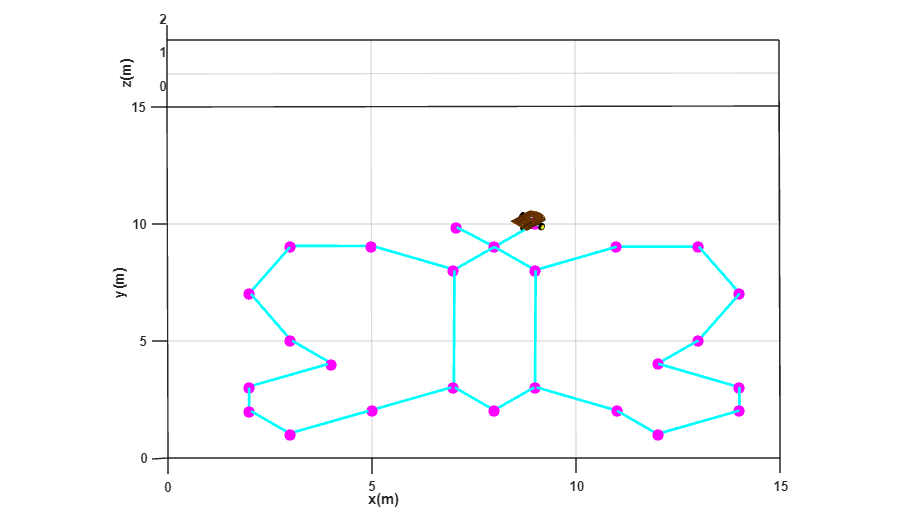

puntosX = [7.08, 8, 9, 11, 13, 14, 13, 12, 14, 14, 12, 11, 9, 9, 7, 7, 8, 5, 3, 2, 3, 4, 2, 2, 3, 5,  9]; 
puntosY = [9.84, 9, 8,  9,  9,  7,  5,  4,  3,  2,  1,  2, 3, 8, 8, 3, 2, 9, 9, 7, 5, 4, 3, 2, 1, 2, 10];

% Dibujar puntos fijos en la escena
plot3(puntosX, puntosY, zeros(size(puntosX)), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'c','lineWidth',2);
    
    pause(ts);

end

#### Gráficas

Finalmente, se muestran las gráficas de las velocidades `u` y `w` a lo largo del tiempo. Se usan subplots para presentar ambas curvas por separado, manteniendo una línea clara y visible. Estas gráficas permiten verificar que las referencias de velocidad se aplicaron correctamente a lo largo de la simulación.

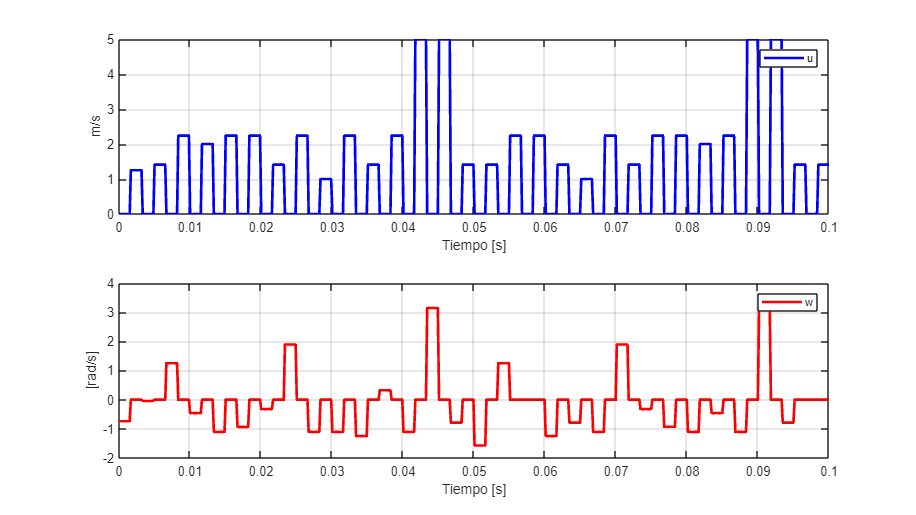

graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

### Control en lazo cerrado

#### Tiempo

A continuación, se establecen los parámetros temporales

ts = 0.1;
t_segmento = 15;
N = t_segmento / ts;
t = linspace(0, ts, N);

#### Lista de puntos deseados

Se establece una matriz con las coordenadas a las cuales se desea que llegue el robot

puntos_deseados = [8,    9;
                   9,    8;
                  11,    9;
                  13,    9;
                  14,    7;
                  13,    5;
                  12,    4;
                  14,    3;
                  14,    2;
                  12,    1;
                  11,    2;
                   9,    3;
                   9,    8;
                   9,    3;
                   8,    2;
                   7,    3;
                   5,    2;
                   3,    1;
                   2,    2;
                   2,    3;
                   4,    4;
                   3,    5;
                   2,    7;
                   3,    9;
                   5,    9;
                   7,    8;
                   7,    3;
                   7,    8;
                   8,    9;
                   9,   10];

#### Condiciones iniciales

Se establece la coordenada inicial, asignando los valores explícitamente en la primera posición de cada vector. 

x1(1) = 7.08; 
y1(1) = 9.84;
phi(1) = pi/2;

#### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx(1) = x1(1);
hy(1) = y1(1);

scale = 4;

#### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

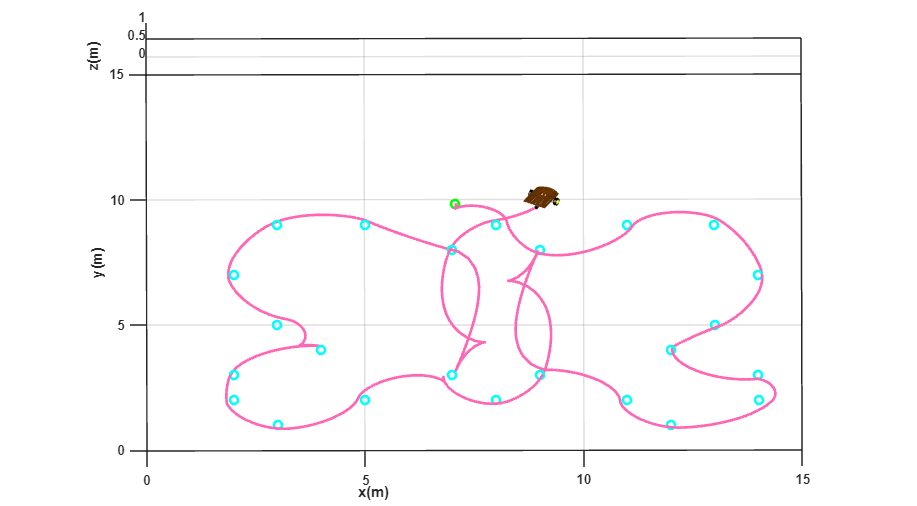

sizeScreen = get(0,'ScreenSize');
scene = figure('Name','Animación trayectoria completa');
set(scene, 'Color','white', 'position', sizeScreen);
set(gca,'FontWeight','bold');
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);
axis([0 15 0 15 0 1]);

% Inicializar trazado
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2); % punto inicial


% Inicialización para cada segmento
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

for i = 1:size(puntos_deseados,1)
    hxd = puntos_deseados(i,1);
    hyd = puntos_deseados(i,2);

    for k = 1:N
        
        hxe = hxd - hx(end);
        hye = hyd - hy(end);
        he = [hxe; hye];
        Error(k) = norm(he);
        
        J = [cos(phi(end)) -sin(phi(end)); sin(phi(end)) cos(phi(end))];

        Kp_base = 0.1;
        Kp_max = 1;
        Error_max = 2.0;
        error_norm = norm(he);
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm/Error_max);
        K = Kp_k * eye(2);
        
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);
        
        % Actualizar estado
        phi(end+1) = phi(end) + w(k)*ts;
        xp1 = v(k)*cos(phi(end-1));
        yp1 = v(k)*sin(phi(end-1));
        x1(end+1) = x1(end) + xp1*ts;
        y1(end+1) = y1(end) + yp1*ts;
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end

    % Actualizar animación del movimiento
    step = 1;
    for k = length(hx)-N+1:step:length(hx)
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % punto objetivo
        pause(ts);
    end
end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

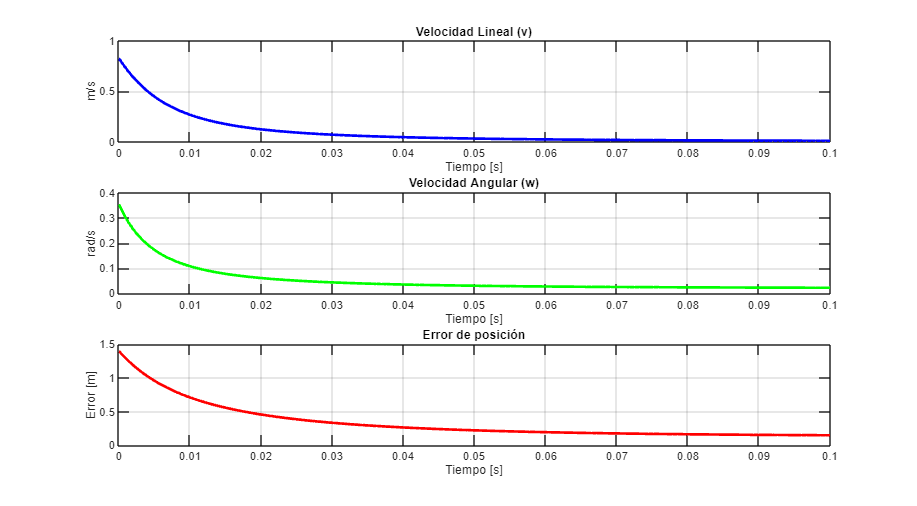

graph = figure('Name',['Gráficas punto ' char(96+i)], 'position', sizeScreen);

subplot(311)
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('m/s');
title('Velocidad Lineal (v)');

subplot(312)
plot(t, w, 'g', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('rad/s');
title('Velocidad Angular (w)');

subplot(313)
plot(t, Error, 'r', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de posición');